## A Closer Inspection of Complex Entropy and Negative Phi Values

## Data Loading

%% Data loading

% Change to directory containing functions, scripts etc.
% Probably don't need the two below lines if this notebook is 
% in your directory with the demo scripts

% If not already in path with data, edit the below
% Otherwise, you probably don't need the next two lines
data_path = '../data/';    % change to path containing ERP data

% Please also make sure that the practical_phi toolbox is within your
% data_path as we be using it to calculate phi. 

% File names with ERP data
file_1 = '153_4sessions_li187';
file_2 = '153_4sessions_li294';

% Load full data structures
data_struct_1 = load(file_1);
data_struct_2 = load(file_2);

% Load relevant ERP data into new variables for easy access
data_1 = data_struct_1(1).allERP;
data_2 = data_struct_2(1).allERP;

% Release data structures from namespace
% Not completely necessary, I just like to do this
clear('data_struct_1');
clear('data_struct_2');

## Running Phi Calculations

T = 200;
tau = 4;

% Trials per bin for covariance matrix calculation
bin_width = 1;

error_points = struct();
processed = struct();
count = 1;

for class = 1:length(data_1)

    % Random number generator seed
    rng(0, 'twister');
    
    current_data_chn_1 = data_1{class};
    current_data_chn_2 = data_2{class};
    
    % bin_centre will be the same for every class since we have the
    % same number of samples. I will, however, include this in every 
    % class - this will be redundant, but I have chosen to do this so all 
    % the needed information is stored within the one structure.
    bin_centres = (T/2):(T/2):(size(current_data_chn_1, 2) - T/2);
    % I have clipped the end by T/2 to ensure we do not iterate beyond the
    % number of samples.
    
    % Initialise matrices to store values of H, I and phi
    num_trials = size(current_data_chn_1, 1);
    num_trial_bins = floor(num_trials / bin_width);
    num_time_bins = length(bin_centres);
    
    values_H = zeros(num_trial_bins, num_time_bins);
    values_I = zeros(num_trial_bins, num_time_bins);
    values_phi = zeros(num_trial_bins, num_time_bins);
    
    % Initialise matrix to store trial numbers in each trial bin
    values_trial_bins = zeros(num_trial_bins, bin_width);
    
    % Randomise the trials in each time bin
    % At the moment, simply done once within each class
    selection_sequence = randperm(num_trials);
    
    % Iterate through every time bin 
    for trial_bin = 0:(num_trial_bins - 1)
        
        % Take the random selection
        selection = selection_sequence((trial_bin * bin_width + 1):((trial_bin + 1) * bin_width));
        
        selection_data_chn_1 = current_data_chn_1(selection, :);
        selection_data_chn_2 = current_data_chn_2(selection, :);
                
        for centre = bin_centres
        
            % Find start and end indices for indexing current data (TIME bin)
            bin_start = centre - (T/2) + 1;
            bin_end = centre + (T/2);
            
            current_selection_chn_1 = selection_data_chn_1(:, bin_start:bin_end);
            current_selection_chn_2 = selection_data_chn_2(:, bin_start:bin_end);
            
            % Calculate phi
            rng(0, 'twister');
            
            [trials_per_bin, ~] = size(current_selection_chn_1);
            
            % Calculating covariance matrices
            Cov_present_cum = zeros(2);
            Cov_cross_cum = zeros(2);
            Cov_past_cum = zeros(2);
        
            for idx_trial = 1:trials_per_bin
        
                data_AB = [current_selection_chn_1(idx_trial, :); current_selection_chn_2(idx_trial, :)];
        
                [Cov_present_curr, Cov_cross_curr, ~, Cov_past_curr] = Cov_comp_shrink(data_AB, tau);
        
                Cov_present_cum = Cov_present_cum + Cov_present_curr;
                Cov_cross_cum = Cov_cross_cum + Cov_cross_curr;
                Cov_past_cum = Cov_past_cum + Cov_past_curr;
        
            end
        
            Cov_present = Cov_present_cum / trials_per_bin;
            Cov_cross = Cov_cross_cum / trials_per_bin;
            Cov_past = Cov_past_cum / trials_per_bin;
        
            %% Phi calculation
            % We use phi_gauss from the practical_phi toolbox (Haun et al 2016) with
            % the assumption that covariance of the past state is the same as
            % covariance of the present state. As we are only using two channels, we
            % undertake the atomic partition by default.
            [phi_pair, ~, ~, ~, I, ~, ~, H] = phi_comp(Cov_present, Cov_cross);
            
            % Only keep first value of phi (non-normalised)
            phi = phi_pair(1);
            
            % Prints to console if negative phi value obtained
            if ~isreal(H)
                error_points(count).Cov_present = Cov_present;
                error_points(count).Cov_cross = Cov_cross;
                error_points(count).Cov_past = Cov_past;
                error_points(count).phi = phi;
                error_points(count).I = I;
                error_points(count).H = H;
                error_points(count).data_1 = current_selection_chn_1;
                error_points(count).data_2 = current_selection_chn_2;
                count = count + 1;
                break
            end
            
            % Add to storage matrices
            bin_index = find(bin_centres == centre);
            values_trial_bins((trial_bin + 1), :) = selection;
            values_H((trial_bin + 1), bin_index) = H;
            values_I((trial_bin + 1), bin_index) = I;
            values_phi((trial_bin + 1), bin_index) = phi;

        end
        
    end
    
    % Write the data to the structure
    processed(class).bin_centres = bin_centres;
    processed(class).values_trial_bins = values_trial_bins;
    processed(class).values_H = values_H;
    processed(class).values_I = values_I;
    processed(class).values_phi = values_phi;
    
end

## Plotting

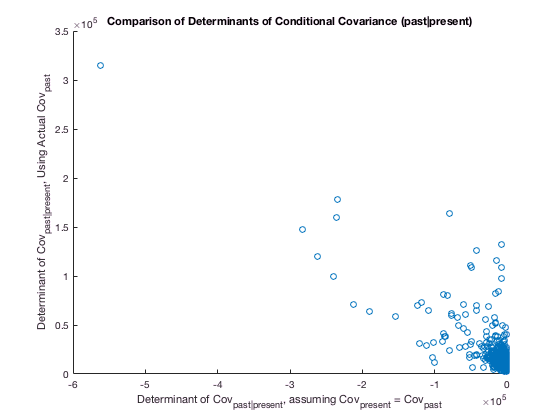

without_past = zeros(length(error_points), 1);
with_past = zeros(length(error_points), 1);

for idx_point = 1:length(error_points)
    
    Cov_present = error_points(idx_point).Cov_present;
    Cov_past = error_points(idx_point).Cov_past;
    Cov_cross = error_points(idx_point).Cov_cross;
    
    without_past(idx_point) = det(Cov_cond(Cov_present, Cov_cross));
    with_past(idx_point) = det(Cov_cond(Cov_present, Cov_cross, Cov_past));   
    
end

figure
scatter(without_past, with_past)
xlabel('Determinant of Cov_{past|present}, assuming Cov_{present} = Cov_{past}');
ylabel('Determinant of Cov_{past|present}, Using Actual Cov_{past}');
title('Comparison of Determinants of Conditional Covariance (past|present)');

It is visible here that all the points are located in the 2nd quadrant i.e. the determinants of the conditional covariance (past given present) can be negative under the assumption that Cov_present = Cov_past; using the actual Cov_past produces a positive determinant (as it should be for a covariance matrix). 

It is clear why a negative determinant for the conditional covariance produces a complex entropy as the calculation of conditional entropy (which assumes a Gaussian distribution for the past and the present) involves the log determinant of the conditional covariance. 

I have previously used the Cov_present = Cov_past assumption for two reasons:

- Using the actual Cov_past produced different phi values using the two phi_toolboxes (Oizumi's PLOS paper toolbox and Haun's toolbox - I have been using Haun for now); the phi values were the same when only Cov_past and the cross covariance were specified.

- Using Oizumi's PLOS paper toolbox produced negative Phi values (in the absence of complex entropy errors, I believe, though this I do not quite remember very well) using the actual Cov_past. 

Using Cov_past does not produce errors, but does produce different phi values. These are plotted below:

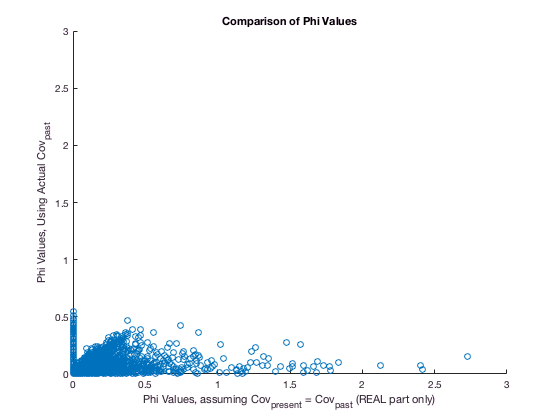

%without_past_phi = load('phi_without_cov_past.mat');
%with_past_phi = load('phi_with_cov_past.mat');

without_past_phi_flat = [];
with_past_phi_flat = [];

for idx_class = 1:5
       
        current_without_past = reshape(without_past_phi.processed(idx_class).values_phi, ...
            numel(without_past_phi.processed(idx_class).values_phi), 1);
        
        current_with_past = reshape(with_past_phi.processed(idx_class).values_phi, ...
            numel(with_past_phi.processed(idx_class).values_phi), 1);
            
        without_past_phi_flat = cat(1, without_past_phi_flat, current_without_past);
        with_past_phi_flat = cat(1, with_past_phi_flat, current_with_past);
end

without_past_phi_flat_plot = real(without_past_phi_flat);

figure
scatter(without_past_phi_flat_plot, with_past_phi_flat)
xlabel('Phi Values, assuming Cov_{present} = Cov_{past} (REAL part only)');
ylabel('Phi Values, Using Actual Cov_{past}');
xlim([0, 3]);
ylim([0, 3]);
title('Comparison of Phi Values');

The plot above uses equal x and y axis limits for more direct comparison and to look at outlier values. For a more closer look at the axes limited to 0.5 on both x and y:

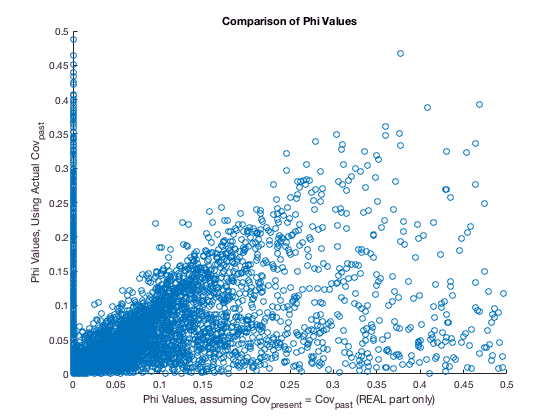

figure
scatter(without_past_phi_flat_plot, with_past_phi_flat)
xlabel('Phi Values, assuming Cov_{present} = Cov_{past} (REAL part only)');
ylabel('Phi Values, Using Actual Cov_{past}');
xlim([0, 0.5]);
ylim([0, 0.5]);
title('Comparison of Phi Values');

## Histogram

T = 200;
tau = 4;

% Trials per bin for covariance matrix calculation
bin_width = 1;

all_points = struct();
count = 1;

for class = 1:length(data_1)

    % Random number generator seed
    rng(0, 'twister');
    
    current_data_chn_1 = data_1{class};
    current_data_chn_2 = data_2{class};
    
    % bin_centre will be the same for every class since we have the
    % same number of samples. I will, however, include this in every 
    % class - this will be redundant, but I have chosen to do this so all 
    % the needed information is stored within the one structure.
    bin_centres = (T/2):(T/2):(size(current_data_chn_1, 2) - T/2);
    % I have clipped the end by T/2 to ensure we do not iterate beyond the
    % number of samples.
    
    % Initialise matrices to store values of H, I and phi
    num_trials = size(current_data_chn_1, 1);
    num_trial_bins = floor(num_trials / bin_width);
    num_time_bins = length(bin_centres);
    
    values_H = zeros(num_trial_bins, num_time_bins);
    values_I = zeros(num_trial_bins, num_time_bins);
    values_phi = zeros(num_trial_bins, num_time_bins);
    
    % Initialise matrix to store trial numbers in each trial bin
    values_trial_bins = zeros(num_trial_bins, bin_width);
    
    % Randomise the trials in each time bin
    % At the moment, simply done once within each class
    selection_sequence = randperm(num_trials);
    
    % Iterate through every time bin 
    for trial_bin = 0:(num_trial_bins - 1)
        
        % Take the random selection
        selection = selection_sequence((trial_bin * bin_width + 1):((trial_bin + 1) * bin_width));
        
        selection_data_chn_1 = current_data_chn_1(selection, :);
        selection_data_chn_2 = current_data_chn_2(selection, :);
                
        for centre = bin_centres
        
            % Find start and end indices for indexing current data (TIME bin)
            bin_start = centre - (T/2) + 1;
            bin_end = centre + (T/2);
            
            current_selection_chn_1 = selection_data_chn_1(:, bin_start:bin_end);
            current_selection_chn_2 = selection_data_chn_2(:, bin_start:bin_end);
            
            % Calculate phi
            rng(0, 'twister');
            
            [trials_per_bin, ~] = size(current_selection_chn_1);
            
            % Calculating covariance matrices
            Cov_present_cum = zeros(2);
            Cov_cross_cum = zeros(2);
            Cov_past_cum = zeros(2);
        
            for idx_trial = 1:trials_per_bin
        
                data_AB = [current_selection_chn_1(idx_trial, :); current_selection_chn_2(idx_trial, :)];
        
                [Cov_present_curr, Cov_cross_curr, ~, Cov_past_curr] = Cov_comp_shrink(data_AB, tau);
        
                Cov_present_cum = Cov_present_cum + Cov_present_curr;
                Cov_cross_cum = Cov_cross_cum + Cov_cross_curr;
                Cov_past_cum = Cov_past_cum + Cov_past_curr;
        
            end
        
            Cov_present = Cov_present_cum / trials_per_bin;
            Cov_cross = Cov_cross_cum / trials_per_bin;
            Cov_past = Cov_past_cum / trials_per_bin;
        
            %% Phi calculation
            % We use phi_gauss from the practical_phi toolbox (Haun et al 2016) with
            % the assumption that covariance of the past state is the same as
            % covariance of the present state. As we are only using two channels, we
            % undertake the atomic partition by default.
            [phi_pair, ~, ~, ~, I, ~, ~, H] = phi_comp(Cov_present, Cov_cross);
            
            % Only keep first value of phi (non-normalised)
            phi = phi_pair(1);
            
            all_points(count).Cov_present = Cov_present;
            all_points(count).Cov_cross = Cov_cross;
            all_points(count).Cov_past = Cov_past;
            all_points(count).phi = phi;
            all_points(count).I = I;
            all_points(count).H = H;
            all_points(count).data_1 = current_selection_chn_1;
            all_points(count).data_2 = current_selection_chn_2;
            count = count + 1;
            
            % Add to storage matrices
            bin_index = find(bin_centres == centre);
            values_trial_bins((trial_bin + 1), :) = selection;
            values_H((trial_bin + 1), bin_index) = H;
            values_I((trial_bin + 1), bin_index) = I;
            values_phi((trial_bin + 1), bin_index) = phi;

        end
        
    end
    
    % Write the data to the structure
    processed(class).bin_centres = bin_centres;
    processed(class).values_trial_bins = values_trial_bins;
    processed(class).values_H = values_H;
    processed(class).values_I = values_I;
    processed(class).values_phi = values_phi;
    
end

Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.095367


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091949


Alert: Complex Entropy
Not Converged. beta=-299.092957


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091675


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092773


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.098145


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-306.706696


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.080322


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.095398


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091797


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.098236


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092255


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092194


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092316


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.093079


Alert: Complex Entropy
Not Converged. beta=-299.096558


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092377


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.063019


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092560


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092133


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092072


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091919


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.093109


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092621


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092255


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091980


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.092224


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091309


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.007538


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091766


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091431


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-300.042236


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Not Converged. beta=-299.091949


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy
Alert: Complex Entropy when we used the fixed covariance for the past


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


Alert: Complex Entropy


det_flat = zeros(length(all_points), 1);

det_flat =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


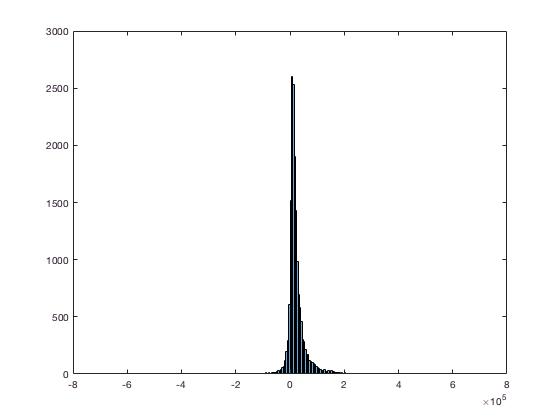

for idx_data = 1:length(all_points)
    
    Cov_present = all_points(idx_data).Cov_present;
    Cov_past = all_points(idx_data).Cov_past;
    Cov_cross = all_points(idx_data).Cov_cross;
    
    det_cov_cond = det(Cov_cond(Cov_present, Cov_cross));
    det_flat(idx_data) = det_cov_cond;
    
end

histogram(det_flat)